# 05 | Frequency-band and aperiodic features

INPUT: fitted spectra from notebook 04; one row per selected segment. OUTPUT: long-format segment_features.csv and one illustrative band-power plot. Two distinct quantities: mean flattened power in dB, integrated linear PSD. The analysis keeps six paper bands. No hard-coded PSD array indices are used.

## 1. Paths and band definitions 

codeDir = 'H:\closed-loop data paper\0 group analysis\GATE-Pain\code\offline data analysis_v2_20260923';
addpath(fullfile(codeDir,'functions'));
outDir=gate_output_dir(codeDir,'05_band_power');
fitDir=gate_output_dir(codeDir,'04_parameterization');
M=readtable(fullfile(fitDir,'processed_manifest.csv'),'TextType','string', ...
    'Delimiter',',','VariableNamingRule','preserve');
bandNames={'delta','theta','alpha','lowbeta','highbeta','gamma'};
bandEdges=[2 4;4 8;8 12;12 20;20 30;40 80];
assert(height(M)>0,'Run notebooks 03 and 04 first.');

## 2. Read one fitted spectrum at a time

rows=cell(height(M)*numel(bandNames),12); rowIndex=0;
for segmentIndex=1:height(M)
    fitFile=fullfile(fitDir,char(M.ExampleID(segmentIndex)+"_fit.mat"));
    S=load(fitFile);
    frequency=S.freq(:); flattenedDb=S.flat_db(:); linearPSD=S.psd_linear(:);
    assert(all(diff(frequency)>0) && all(isfinite(flattenedDb)));

    % Summarize each band / 计算两种功率
    for bandIndex=1:numel(bandNames)
        lower=bandEdges(bandIndex,1); upper=bandEdges(bandIndex,2);
        % Half-open [lower, upper) matches the original flattened-power code.
        flatMask=frequency>=lower & frequency<upper;
        % Both endpoints enter integration of the unflattened linear PSD.
        absoluteMask=frequency>=lower & frequency<=upper;
        assert(any(flatMask) && nnz(absoluteMask)>=2);
        meanFlattenedDb=mean(flattenedDb(flatMask));
        absolutePower=trapz(frequency(absoluteMask),linearPSD(absoluteMask));
        rowIndex=rowIndex+1;
        rows(rowIndex,:)={char(M.ExampleID(segmentIndex)),char(M.RatID(segmentIndex)), ...
            char(M.Strategy(segmentIndex)),char(M.Phase(segmentIndex)),bandNames{bandIndex}, ...
            meanFlattenedDb,absolutePower,S.offset_db,S.exponent,S.knee,S.r_squared,S.fit_error};
    end
end

## 3. Save an explicit long-format table

Offset is converted to dB once in notebook 04. Do not multiply it again. The native knee and exponent parameters do not get the dB factor of ten.

T=cell2table(rows,'VariableNames',{'ExampleID','RatID','Strategy','Phase','Band', ...
    'Power_dB','AbsolutePower_inputUnitSquared','Offset_dB','Exponent','Knee','FitR2','FitError_log10'});
writetable(T,fullfile(outDir,'segment_features.csv'));
save(fullfile(outDir,'segment_features.mat'),'T','bandNames','bandEdges');
disp(T(1:min(12,height(T)),:));

              ExampleID                RatID        Strategy       Phase         Band        Power_dB    AbsolutePower_inputUnitSquared    Offset_dB    Exponent     Knee       FitR2     FitError_log10
    _____________________________    _________    ____________    _______    ____________    ________    ______________________________    _________    ________    _______    _______    ______________

    {'Rat07_130Hz_OL_Pre_seg010'}    {'Rat07'}    {'130Hz_OL'}    {'Pre'}    {'delta'   }     0.28612                3.9041                 7.2174      0.85957     0.51961    0.94988       0.050453   
    {'Rat07_130Hz_OL_Pre_seg010'}    {'Rat07'}    {'130Hz_OL'}    {'Pre'}    {'theta'   }      3.0603                8.6945                 7.2174      0.85957     0.51961    0.94988       0.050453   
    {'Rat07_130Hz_OL_Pre_seg010'}    {'Rat07'}    {'130Hz_OL'}    {'Pre'}    {'alpha'   }       2.933                5.3292                 7.2174      0.85957     0.51961    0.94988       0.0504

## 4. Inspect one segment's band summaries

A within-segment band summary is not an animal-level group comparison.

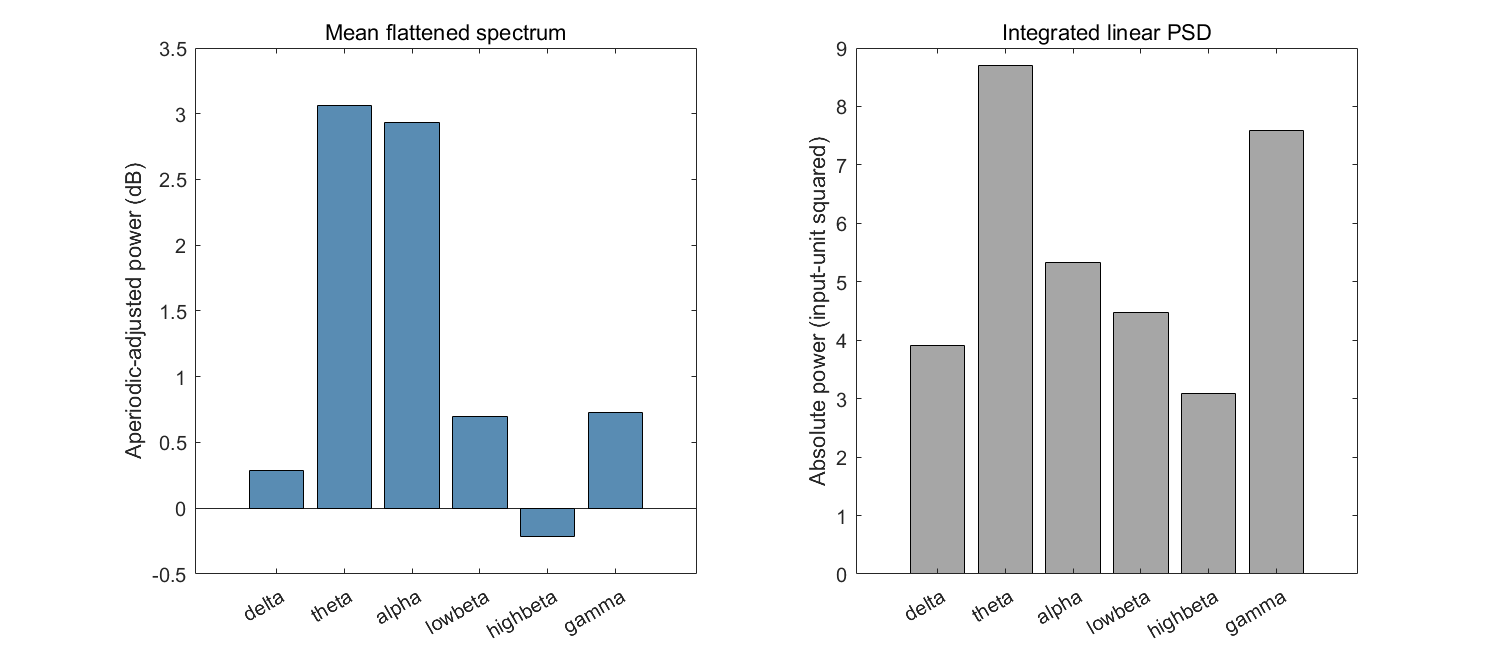

firstSegment=T(1:numel(bandNames),:);
fig=figure('Color','w','Position',[100 100 1000 430]);
subplot(1,2,1); bar(firstSegment.Power_dB,'FaceColor',[0.35 0.55 0.7]);
set(gca,'XTick',1:6,'XTickLabel',bandNames); xtickangle(30);
ylabel('Aperiodic-adjusted power (dB)'); title('Mean flattened spectrum');
subplot(1,2,2); bar(firstSegment.AbsolutePower_inputUnitSquared,'FaceColor',[0.65 0.65 0.65]);
set(gca,'XTick',1:6,'XTickLabel',bandNames); xtickangle(30);
ylabel('Absolute power (input-unit squared)'); title('Integrated linear PSD');
exportgraphics(fig,fullfile(outDir,'band_power_example.png'),'Resolution',180);

fprintf('Saved %d segments x 6 bands. Next: step06_rat_level_summary.\n',height(M));

Saved 12 segments x 6 bands. Next: step06_rat_level_summary.
